# Stock Data - Covariance Stationarity

In this exercise, you will quantify the risk for a portfolio (a collection of stocks) by computing its rolling variance. To compute the variance of a portfolio, you need to compute the covariance matrix to identify dependencies between different stocks.

## 1.

Load data from `stockData_withReturns.mat`.

load stockData_withReturns.mat

## 2. 

Estimate the 90-day rolling covariance matrix of the returns. To do this, loop over the returns and use the `cov`function in each 90-day period. Store each covariance matrix as a new page in a 3-D matrix, `cMat`, of size 122-by-122-by-1186.

window = 90;
cMat = zeros(size(rets,2), size(rets,2), size(rets,1)-window);
for k=1:size(rets,1)-window
    cMat(:,:,k) = cov(rets(k:k+window-1, :));
end

## 3. 

Use the `ones`function to create a row vector, `w`, of equal weights for each stock. The sum of the weights should be one.

w = ones(1, size(rets,2)) * 1/size(rets,2);
sum(w)

ans = 1.0000

## 4.

1.Compute the risk (variance) of the portfolio for each rolling 90-day period. To do this, loop over the pages of `cMat`and use the following equation: `Risk(k) = w*cMat(:,:,k)*w'`. Plot the risk over time.

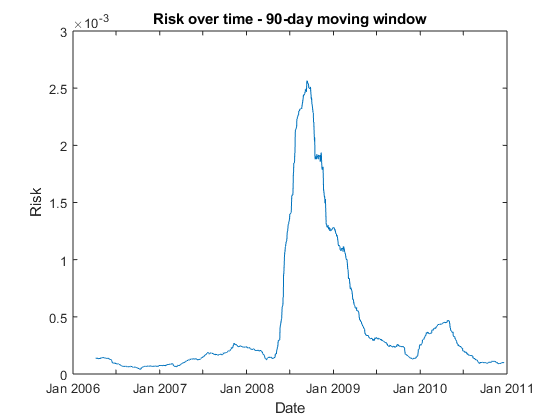

risk = zeros(size(rets,1)-window, 1);
for k=1:size(rets,1)-window
    risk(k) = w*cMat(:,:,k)*w';
end

plot(stockPrices.Date(1:size(risk,1)), risk)
title('Risk over time - 90-day moving window')
xlabel('Date')
ylabel('Risk')

## BONUS

Find the exponentially-weighted covariance for a 90-day moving window using `ewstats`(Financial Toolbox™)and a decay factor of 0.97. Calculate the risk using this new covariance measurement and plot the result on top of the risk measurement from step 4.

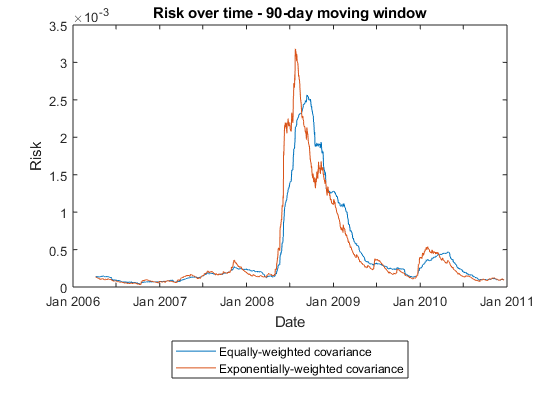

cMat_uneq = zeros(size(cMat));
risk_uneq = zeros(size(risk));

for k=1:size(rets,1)-window
    [~, cMat_uneq(:,:,k)] = ewstats(rets(k:k+window-1, :), 0.97);
    risk_uneq(k) = w*cMat_uneq(:,:,k)*w';
end

hold on
plot(stockPrices.Date(1:size(risk,1)), risk_uneq)
hold off
legend('Equally-weighted covariance', 'Exponentially-weighted covariance', 'Location', 'southoutside')